Nx = 1024;
Ny = 1024;


% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Cambio
dx =0.1*um;
dy =0.1*um;

waveLength = 650*nm;

% Ditancia Propagación
zlim = Nx*dx^2/waveLength;
z = 1.5* zlim;

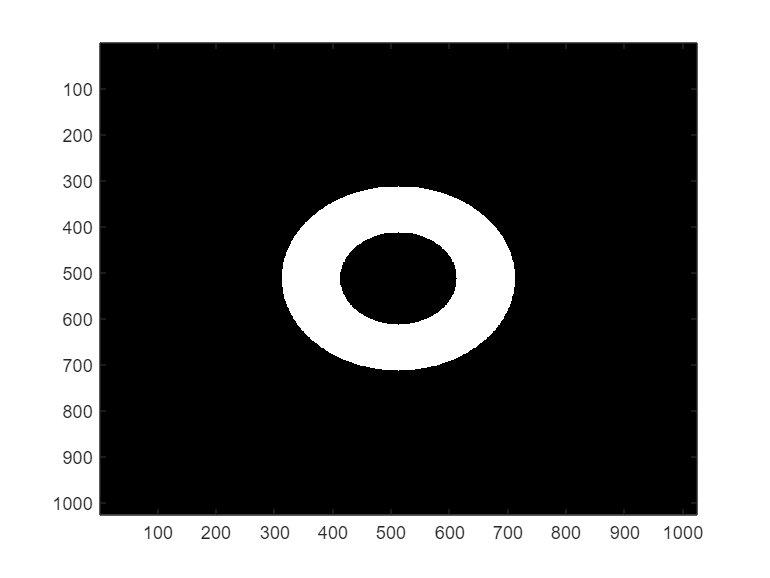

% Transmitancia
radio = 10*um/dx;
aberturaCircular = ~filtroCircular ([Nx/2 Ny/2],2*radio,[Ny Nx]);
obstaculoCirular = filtroCircular ([Nx/2 Ny/2],radio,[Ny Nx]);

pantalla =~(aberturaCircular+obstaculoCirular);
pantalla2 = (obstaculoCirular);

imagesc(pantalla)
colormap gray

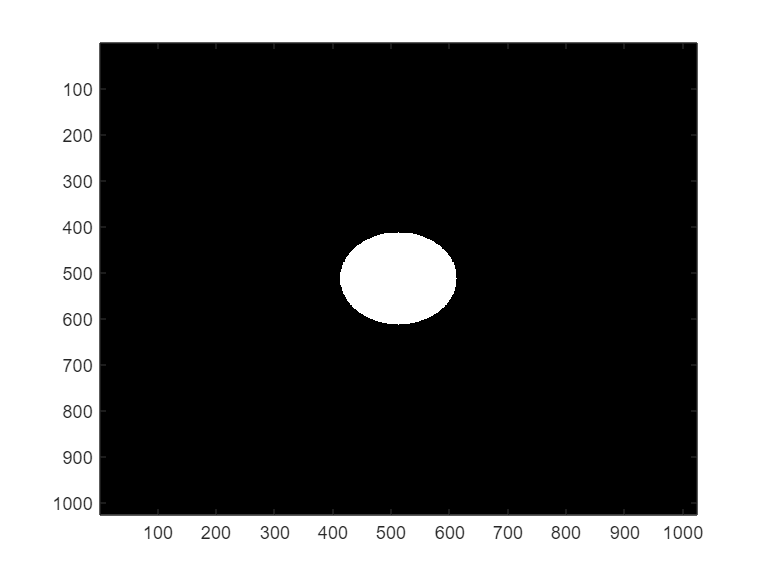

imagesc(pantalla2)
colormap gray

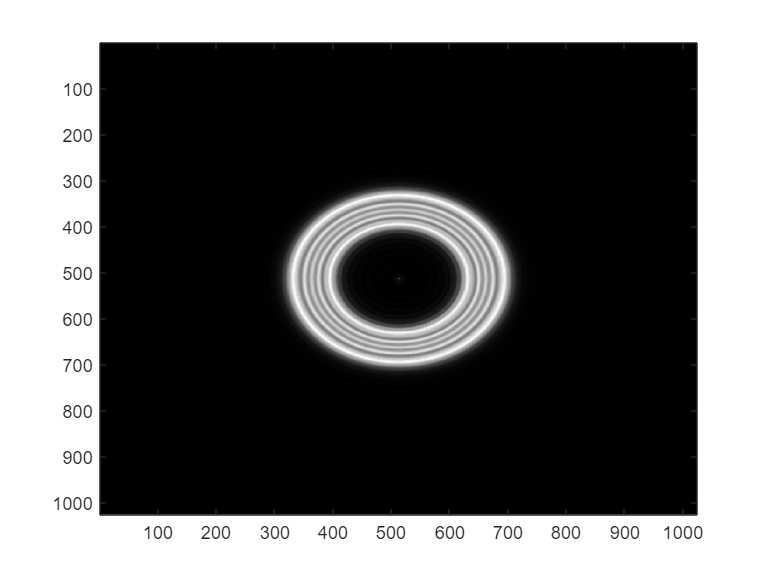

propagacionPantalla1 = transformadaFresnel(pantalla,dx,dy,z,waveLength,"dft",false);
intensidad1 = abs(propagacionPantalla1).^2;
imagesc(intensidad)

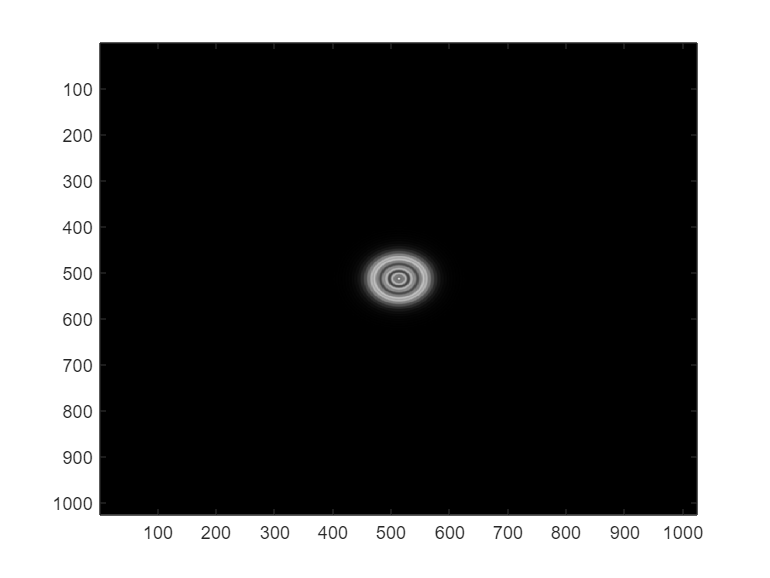

propagacionPantalla2 = transformadaFresnel(pantalla2,dx,dy,z,waveLength,"dft",false);
intensidad2 = abs(propagacionPantalla2).^2;
imagesc(intensidad2)

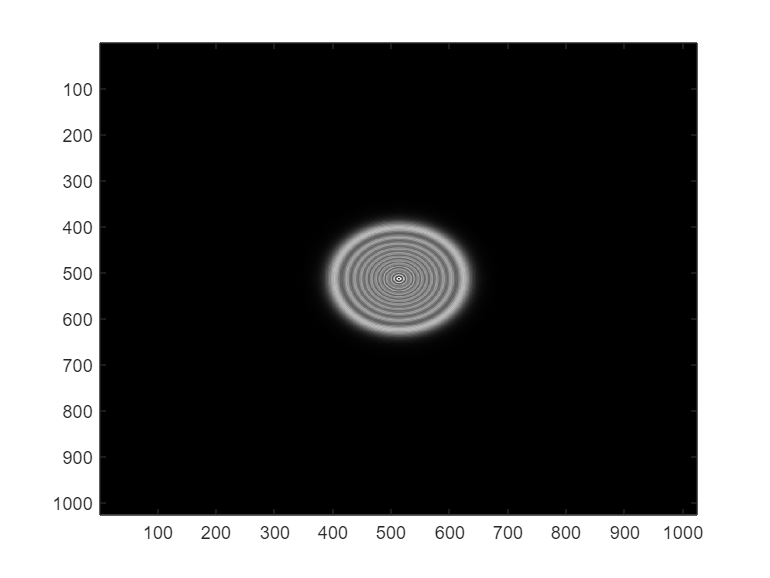

superPosicion = propagacionPantalla1+propagacionPantalla2;
imagesc(abs(superPosicion).^2)

aberturaCircularProp = transformadaFresnel(~aberturaCircular,dx,dy,z,waveLength,"dft",false);
intensidad3 = abs(aberturaCircularProp).^2;
imagesc(intensidad3)